clear
% kappa_ext = 1.2323e6;
% kappa_int = .22653e6;
kappa_ext = .971e6;
kappa_int = .936e6;
kappa_tot = kappa_ext + kappa_int;% 1.5e6; %kappa_int = 0.2265MHz. These values correspond to ng = 0 and phi = 0 for Jules' sample in March 2021 small fridge
% kerr = 0;
kerr = -.5e6;
detunings = linspace(-5*kappa_tot, 5*kappa_tot, 1000);
omega_0 = 5.7851e9; % in Hz. 
h = 6.626e-34; % just h, not hbar since omega_0 is in Hz
plot_figures = 1;
input_attenuation = 81; 

power_input_start_dBm = -63 -input_attenuation; 
power_input_stop_dBm = -32 -input_attenuation; % input_attenuationdB is approx fridge attenuation. 
power_input_start_watts = 1e-3.*10.^(power_input_start_dBm/10);
power_input_stop_watts = 1e-3.*10.^(power_input_stop_dBm/10);

% power_input_in_watts = linspace(power_input_start_watts, power_input_stop_watts, 5);
% power_input_in_dBm = 10*log10(power_input_in_watts/1e-3);

power_input_in_dBm = linspace(power_input_start_dBm, power_input_stop_dBm, 100);
power_input_in_watts = 1e-3.*10.^(power_input_in_dBm/10);

power_input_in_numbers = power_input_in_watts/h/omega_0;
kerr = kerr/1e6;
kappa_ext = kappa_ext /1e6;
kappa_tot = kappa_tot/ 1e6;
detunings = detunings/ 1e6;
power_input_in_numbers = power_input_in_numbers/1e6;
[detunings_array, power_input_array] = meshgrid(detunings, power_input_in_numbers);
amp_roots = zeros([size(detunings_array),3]);

for i = 1: size(detunings_array,1)
    for j = 1: size(detunings_array,2)
        amp_roots(i,j,:) = roots([kerr^2, -2*kerr.*detunings_array(i,j), (detunings_array(i,j).^2 + kappa_tot^2 / 4),...
            -kappa_ext * power_input_array(i,j)]);
    end
end

amp_roots(imag(amp_roots) ~=0) = 0;
main_s11_forward = zeros([size(detunings_array)]);
main_s11_reverse = zeros([size(detunings_array)]);
main_s11_forward_power = zeros([size(detunings_array)]);
main_s11_reverse_power = zeros([size(detunings_array)]);
first_zero_root_1 = zeros(size(detunings_array,1),1);
first_zero_root_3 = zeros(size(detunings_array,1),1);

detunings_array_reps = repmat(detunings_array, [1, 1, 3]);
s11 = ((detunings_array_reps - kerr .* amp_roots) - 1i*(kappa_tot -...
2*kappa_ext)/2)./((detunings_array_reps - kerr .* amp_roots) -1i*kappa_tot/2);
s11(amp_roots == 0) = 5;
for i = 1: size(detunings_array,1)
    number_zeros_1 = sum(double(amp_roots(i,:,1) == 0));
    number_zeros_3 = sum(double(amp_roots(i,:,3) == 0));
    if number_zeros_1 > 0 && number_zeros_3 > 0
        first_zero_root_3(i) = find(amp_roots(i,:,3) == 0, 1) - 1;
        first_zero_root_1(i) = length(amp_roots(i,:,1)) - find(flip(amp_roots(i,:,1) ~= 0),1) + 1;
        main_s11_reverse_temp = s11(i,:,1);
        s11_3_temp = s11(i,:,3);
        zero_entries = (main_s11_reverse_temp == 5);
        main_s11_reverse_temp(zero_entries) = s11_3_temp(zero_entries);
        main_s11_forward(i,:) = [s11(i,1:first_zero_root_3(i),3), s11(i,first_zero_root_3(i) + 1: first_zero_root_1(i), 1), s11(i,first_zero_root_1(i) + 1: end, 3)]; 
        main_s11_reverse(i,:) = main_s11_reverse_temp;
    else 
        main_s11_forward = s11(:,:,3);
        main_s11_reverse = s11(:,:,3);
    end
end
for i = 1: size(power_input_array,2)
    number_zeros_1 = sum(double(amp_roots(:,i,1) == 0));
    number_zeros_3 = sum(double(amp_roots(:,i,3) == 0));
    if number_zeros_1 > 0 && number_zeros_3 > 0
        first_zero_root_3(i) = find(amp_roots(:,i,3) == 0, 1) - 1;
        first_zero_root_1(i) = length(amp_roots(:,i,1)) - find(flip(amp_roots(:,i,1) ~= 0),1) + 1;
        main_s11_reverse_temp_power = s11(:,i,1);
        s11_3_temp = s11(:,i,3);
        zero_entries = (main_s11_reverse_temp_power == 5);
        main_s11_reverse_temp_power(zero_entries) = s11_3_temp(zero_entries);
        main_s11_forward_power(:,i) = [s11(1:first_zero_root_3(i),i,3); s11(first_zero_root_3(i) + 1: end,i, 1)];         
%         main_s11_forward_power(:,i) = [s11(1:first_zero_root_3(i),i,3); s11(first_zero_root_3(i) + 1: first_zero_root_1(i),i, 1); s11(first_zero_root_1(i) + 1: end,i, 3)]; 
        main_s11_reverse_power(:,i) = main_s11_reverse_temp_power;
%     else 
%         main_s11_forward_power = s11(:,:,3);
%         main_s11_reverse_power = s11(:,:,3);
    end
end

probability_root_1 = 0.3;
probability_array = zeros(size(s11));
probability_array(:,:,1) = probability_root_1;
probability_array(:,:, 3) = 1 - probability_root_1;
probability_array(s11 == 5) = 0;
probability_array_sum = sum(probability_array, 3);
probability_array_sum = repmat(probability_array_sum, 1, 1,3);
probability_array(probability_array >0 & probability_array_sum == probability_root_1) = 1;
probability_array(probability_array >0 & probability_array_sum == 1 - probability_root_1) = 1;

s11_averaged = squeeze(sum(probability_array.*s11,3));

figure
    color_array = ['r', 'b', 'k', 'g', 'm'];
    i = 1;
    j = 1;
    while i<100
        detunings_array_1 = detunings_array(i,:);
        s11_averaged_root_1_temp = s11_averaged(i,:);
       
        root_1_color_prop = [color_array(j) 'x'];
        plot(detunings_array_1, wrapTo360(angle(s11_averaged_root_1_temp)*180/pi),root_1_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 1'])
        hold on
        xlabel('Detuning (MHz)')
        ylabel('Phase (degs)')
        title(['All roots phase for several input powers with Kerr = ' num2str(kerr) 'MHz'])
        i = i + 20;
        j = j + 1;
    end
    h = zeros(5,1);
    h(1) = plot(nan, nan, 'r');hold on
    h(2) = plot(nan, nan, 'b');
    h(3) = plot(nan, nan, 'k');
    h(4) = plot(nan, nan, 'g');
    h(5) = plot(nan, nan, 'm');
    legend (h, [num2str(power_input_in_dBm(1) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(21) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(41) + input_attenuation) 'dBm'],...
        [num2str(power_input_in_dBm(61) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(input_attenuation) + input_attenuation) 'dBm'], 'stable root 1', 'unstable root', 'stable root 2')

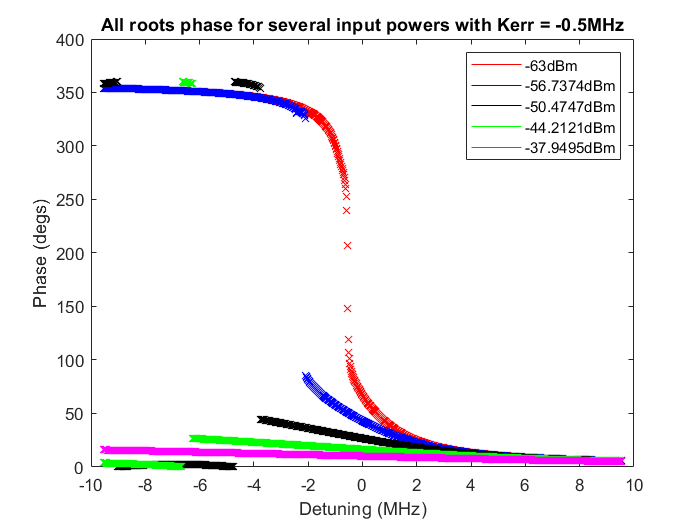

     hold off

figure
    color_array = ['r', 'b', 'k', 'g', 'm'];
    i = 1;
    j = 1;
    while i<100
        detunings_array_1 = detunings_array(i,:);
        s11_averaged_root_1_temp = s11_averaged(i,:);
       
        root_1_color_prop = [color_array(j) 'x'];
        plot(real(s11_averaged_root_1_temp), imag(s11_averaged_root_1_temp),root_1_color_prop)%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 1'])
        hold on
        axis([-1 1 -1 1])
        xlabel('Re(S11)')
        ylabel('Im(S11)')
        title(['All roots phase for several input powers with Kerr = ' num2str(kerr) 'MHz'])
        i = i + 20;
        j = j + 1;
    end
    h = zeros(5,1);
    h(1) = plot(nan, nan, 'rx');hold on
    h(2) = plot(nan, nan, 'bx');
    h(3) = plot(nan, nan, 'kx');
    h(4) = plot(nan, nan, 'gx');
    h(5) = plot(nan, nan, 'mx');
    legend (h, [num2str(power_input_in_dBm(1) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(21) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(41) + input_attenuation) 'dBm'],...
        [num2str(power_input_in_dBm(61) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(input_attenuation) + input_attenuation) 'dBm'], 'stable root 1', 'unstable root', 'stable root 2')

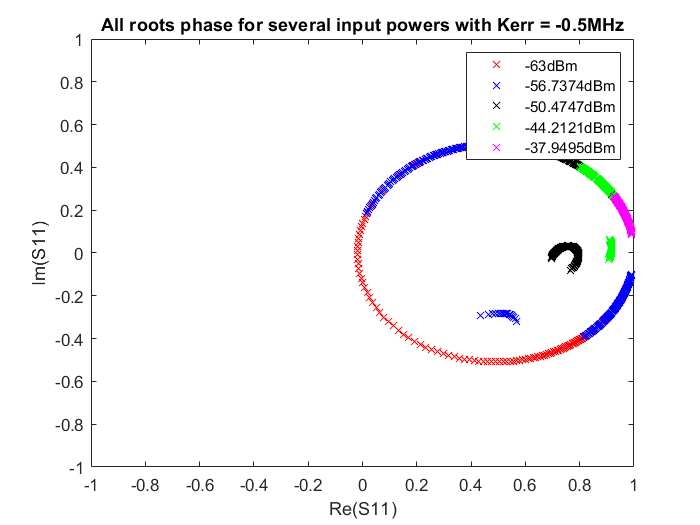

     hold off

figure
    color_array = ['r', 'b', 'k', 'g', 'm'];
    i = 1;
    j = 1;
    while i<100
        detunings_array_1 = detunings_array(i,:);
        s11_averaged_root_1_temp = s11_averaged(i,:);
       
        root_1_color_prop = [color_array(j) 'x'];
        plot(detunings_array_1, abs(s11_averaged_root_1_temp),root_1_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 1'])
        hold on
        xlabel('Detuning (MHz)')
        ylabel('|S11|')
        title(['All roots phase for several input powers with Kerr = ' num2str(kerr) 'MHz'])
        i = i + 20;
        j = j + 1;
    end
    h = zeros(5,1);
    h(1) = plot(nan, nan, 'r');hold on
    h(2) = plot(nan, nan, 'b');
    h(3) = plot(nan, nan, 'k');
    h(4) = plot(nan, nan, 'g');
    h(5) = plot(nan, nan, 'm');
    legend (h, [num2str(power_input_in_dBm(1) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(21) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(41) + input_attenuation) 'dBm'],...
        [num2str(power_input_in_dBm(61) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(input_attenuation) + input_attenuation) 'dBm'], 'stable root 1', 'unstable root', 'stable root 2')

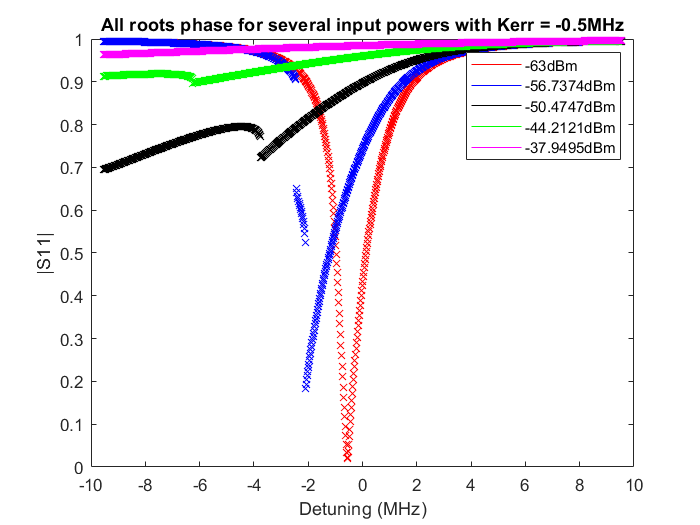

     hold off